%%  FM320 Course Project - Candidate Number: 22370 %%

clc; % Clear command window
clear variables; % Clear all variables from workspace
clf; % Clears figure window
close all; % Close all windows
fign = 1 ; % Figure counter

# Loading and exploring the data

% Loading the data
data = xlsread('FM320_data.xlsx','E9:X7808') ; % These are the log returns for all the stocks
tickers = {'MSFT ','XOM ','FB ','CVX ','GOOG ','APPL ','PFE ','JNJ ','WFC ','JPM ','WMT ','BAC ','VZ ','T ','HD ','AMZN ','GOOGL ','MA ','UNH ','V'};
n_stocks = size(data,2);
[~,dates] = xlsread('FM320_data.xlsx','Y9:Y7808') ; % Return the dates in 'text' format
dn = datenum(dates,'yyyy-mm-dd'); % Convert date to serial
T = size(dates,1);
start_date = dn(1,1);
end_date = dn(T,1);
dn = datetime(dn,'ConvertFrom','datenum');

log_returns = data(:,[1,10]) ; % Selecting the log returns for MSFT and JPM
sum(isnan(log_returns)) ; % This is equal to (0,0) so we have no missing values for the log returns series

% Exploring the MSFT & JPM returns data and computing some statistics 

AvgRet = mean(log_returns);
StdDevRet = std(log_returns);
MaxRet  = max(log_returns);
MinRet = min(log_returns);
SkewRet = skewness(log_returns);
KurtRet = kurtosis(log_returns);
Statistics = [AvgRet; StdDevRet; MaxRet; MinRet; SkewRet; KurtRet];


DailyStats = table(Statistics(:,1),Statistics(:,2),...
          'VariableNames',{'MSFT','JPM'},...
          'RowNames',{'Average'; 'Std. Dev.'; 'Max'; 'Min'; ...
                           'Skewness'; 'Kurtosis'})

DailyStats = 6×2 table
                    MSFT          JPM    
                 __________    __________

    Average      0.00081056    0.00045248
    Std. Dev.      0.020195      0.023878
    Max             0.17869       0.22392
    Min            -0.16958      -0.23228
    Skewness       -0.02241       0.21748
    Kurtosis         9.3304        14.402


# Determining the optimal portfolio weights

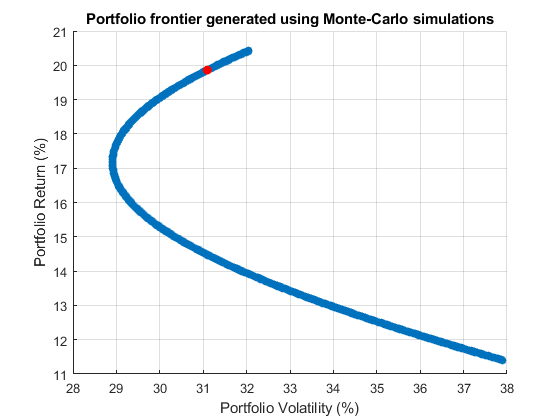

% Using Monte-Carlo simulations to obtain optimal weights combination which maximises the sharpe ratio
% https://blog.quantinsti.com/portfolio-optimization-maximum-return-risk-ratio-python/

annualised_return = 252 * mean(log_returns) ; % This is a 1x2 matrix
annualised_covariance = 252 * cov(log_returns) ; % Annualised covariance 2x2 matrix 

n_sims = 1000000;
weights = NaN(n_sims,2); % Matrix to store the weights generated in each simulation
rets = NaN(n_sims,1); % Expected portfolio returns matrix
vols = NaN(n_sims,1); % Portfolio volatility matrix
sharpes = NaN(n_sims,1); % Sharpe ratio matrix

% We assume that risk free rate is zero

for i = 1:n_sims 
    
    sim_weights = rand(2,1); % Generate 1x2 matrix of random numbers from Uniform(0,1)
    sim_weights = sim_weights / sum(sim_weights); % Normalize to set the sum to 1
    weights(i,:) =  sim_weights;
    rets(i) = annualised_return * sim_weights; % (r'w) 
    vols(i) = sqrt( sim_weights' * annualised_covariance * sim_weights ); %  sqrt(w'Σw) 
    sharpes(i) = rets(i)/vols(i);  % rf=0
    
end

[best_sharpe, argmax] =  max(sharpes); % Finding the Weights Corresponding to the greatest sharpe ratio
optimal_weights = weights(argmax , :)'; % Optimal portfolio consists of investing 93.7% of the wealth in MSFT, and 6.3% in JPM

% Visualising the results from the simulations
% Red dot is the optimal weights portfolio

figure(fign)
scatter(100*vols , 100*rets , 'filled');
hold on
grid on
scatter(100*vols(argmax) , 100*rets(argmax) , 'MarkerEdgeColor','red','MarkerFaceColor','red'); % Marking the portfolio which gives the max. sharpe ratio
xlabel('Portfolio Volatility (%)');
ylabel('Portfolio Return (%)');
title('Portfolio frontier generated using Monte-Carlo simulations');
hold off

fign = fign+1;

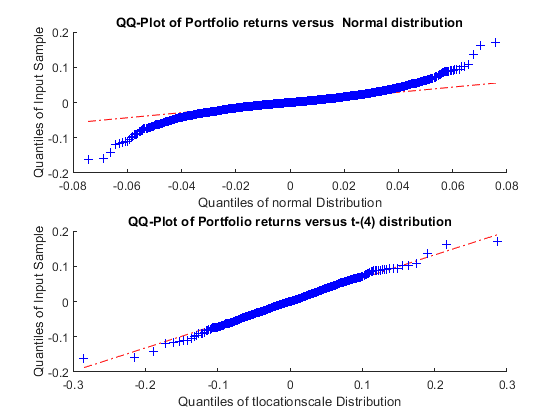

portfolio_returns = log_returns * optimal_weights ; % This is a column vector of the portfolio returns

demeaned_returns = log_returns - mean(log_returns); % De-mean the returns before fitting models

% From these QQ-Plots we can see that the returns exhibit fat tails and are much more likely to come from a t-distribution rather than a Normal

figure(fign)
subplot(2,1,1)
qqplot(portfolio_returns , makedist('Normal','mu',mean(portfolio_returns),'sigma',std(portfolio_returns)))  
title('QQ-Plot of Portfolio returns versus  Normal distribution')
subplot(2,1,2)
qqplot(portfolio_returns , makedist('tLocationScale','mu',mean(portfolio_returns),'sigma',std(portfolio_returns),'nu',4))
title('QQ-Plot of Portfolio returns versus t-(4) distribution')

fign = fign+1;

% Jarque-Bera test to check for normality of returns, we reject H0 so portfolio returns are not Normal
[h,pval,jbstat,critval] = jbtest(portfolio_returns);

# Estimating Bivariate conditional volatility models

% 1) Estimating a 1-lag BEKK model

[parBEKK,~,hBEKK,vcvBEKK] = bekk(demeaned_returns,[],1,0,1,'Full'); % Fitting a 'full' model with all 11 parameters

____________________________________________________________
   Diagnostic Information

Number of variables: 11

Functions 
Objective:                            bekk_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
Nonlinear constraints:                bekk_constraint
Nonlinear constraints gradient:       finite-differencing

Constraints
Number of nonlinear inequality constraints: 4
Number of nonlinear equality constraints:   0
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      0
Number of lower bound constraints:          8
Number of upper bound constraints:          8

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      12   

% Calculating the model's estimated parameters' standard errors

BEKK_params_SE = nan(11,1); % We have 11 BEKK parameters

for i = 1:11
    BEKK_params_SE(i,1) = sqrt(vcvBEKK(i,i)); % Diagonal elements of vcvBEKK are the variances of the BEKK parameters
end

% Testing the statistical significance of the BEKK model parameters using a t-statistic 

BEKK_params_tScores = parBEKK ./ BEKK_params_SE ; % t = (estimated param. - 0) / ( SE(estimated param.) ) 

BEKK_p_vals = (1-normcdf(BEKK_params_tScores)) ;

% Note: The very small t-scores values of some parameters shows that
% those parameters are not statistically different from 0 and the model is potentially overparametrized  

BEKK_param_table = array2table([parBEKK , BEKK_params_SE , BEKK_params_tScores , BEKK_p_vals],...
    "VariableNames",["Estimated parameter value","Standard errors","t-scores","P-Values"]) 

BEKK_param_table = 11×4 table
    Estimated parameter value    Standard errors    t-scores     P-Values 
    _________________________    _______________    ________    __________

             0.0034822             0.00033211         10.485             0
             0.0029859             0.00077019         3.8768    5.2914e-05
           -0.00066528              0.0023147       -0.28742        0.6131
               0.16094               0.021684         7.4219    5.7732e-14
            -0.0087952               0.023781       -0.36985       0.64425
              0.067127               0.046731         1.4364      0.075439
               0.18667               0.027542         6.7776    6.1116e-12
               0.96564              0.0073643         131.12             0
             0.0016109               0.008347        0.19299       0.42348
        


MSFT_BEKK_var = reshape(hBEKK(1,1,:),T,1); % Microsoft conditional variance series
JPM_BEKK_var = reshape(hBEKK(2,2,:),T,1); % JP Morgan conditional variance series

corrBEKK = reshape(hBEKK(1,2,:),T,1) ./ ( sqrt(MSFT_BEKK_var) .* sqrt(JPM_BEKK_var) ); % MSFT-JPM Correlation series

% Estimate the portfolio conditional variance series using BEKK
portfolio_var_BEKK = nan(T,1); 

for t = 1:T
    portfolio_var_BEKK(t,1) = optimal_weights' * hBEKK(:,:,t) * optimal_weights ; % This is: w' * Σt * w 
end

portfolio_vol_BEKK = sqrt(portfolio_var_BEKK); % Calculating portfolio conditional volatility 

% 2) DCC using a GARCH(1,1) for the univariate volatility series

[parDCC,~,hDCC] = dcc(demeaned_returns,[],1,0,1); % Fitting a DCC model with 1 lag

____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.148804e+04    0.000e+00    4.428e+01
    1      11    2.148783e+04    0.000e+00    1.483e+02    4.281e-03
    2      15    2.148712e+04    0.000e+00    

MSFT_DCC_var = reshape(hDCC(1,1,:),T,1); % Microsoft conditional variance series
JPM_DCC_var = reshape(hDCC(2,2,:),T,1); % JP Morgan conditional variance series

corrDCC = reshape(hDCC(1,2,:),T,1) ./ (sqrt(MSFT_DCC_var) .* sqrt(JPM_DCC_var)); % MSFT-JPM Correlation series

% Estimate the portfolio conditional variance series using DCC
portfolio_var_DCC = nan(T,1); 

for t = 1:T
    portfolio_var_DCC(t,1) = optimal_weights' * hDCC(:,:,t) * optimal_weights ; % This is  w' * Σt * w 
end

portfolio_vol_DCC = sqrt(portfolio_var_DCC); % Calculating portfolio conditional volatility 


% 3) Orthogonal GARCH Model using PCA

% PCA Analysis
[weights, princomp, eigenvals, explvar] = pca(demeaned_returns); 

Tweights = array2table([weights'; eigenvals'; 100 * explvar'],...   
    "VariableNames",{'PC1' 'PC2'},...
    "RowNames",[{'MSFT','JPM'}' ;{'Eigenvalues - Explained Var'}; {'% Total Var'}])

Tweights = 4×2 table
                                      PC1           PC2    
                                   __________    __________

    MSFT                              0.55631      -0.83098
    JPM                               0.83098       0.55631
    Eigenvalues - Explained Var    0.00070187    0.00027599
    % Total Var                        71.776        28.224


% We can see the common market risk factor explains 72% of the variation while 28% is explained by the idiosyncratic risk factor 
% Since we only have two stocks, we perform O-GARCH with a single principal component

n_factors = 1 ; % We use just a single factor

% Fitting a Multivariate O-GARCH(1,1) model
[params_OGARCH,hOGARCH,~,~] = o_mvgarch(demeaned_returns,n_factors,1,0,1); 

MSFT_OGARCH_var = reshape(hOGARCH(1,1,:),T,1); % Microsoft conditional variance series
JPM_OGARCH_var = reshape(hOGARCH(2,2,:),T,1); % JP Morgan conditional variance series

corrOGARCH = reshape(hOGARCH(1,2,:),T,1) ./ (sqrt(MSFT_OGARCH_var) .* sqrt(JPM_OGARCH_var)); % MSFT-JPM Correlation series

% Estimate the portfolio conditional variance series using DCC
portfolio_var_OGARCH = nan(T,1); 

for t = 1:T
    portfolio_var_OGARCH(t,1) = optimal_weights' * hOGARCH(:,:,t) * optimal_weights ; % This is  w' * Σt * w 
end

portfolio_vol_OGARCH = sqrt(portfolio_var_OGARCH); % Calculating portfolio conditional volatility

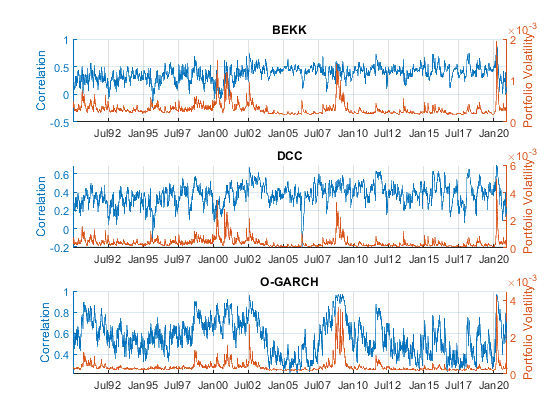

% Comparing the multivariate models to choose the best one and proceed to the VaR calculations 

figure(fign)
subplot(3,1,1)
hold on;
grid on;
title('BEKK')
yyaxis left
plot(dn,corrBEKK) % Plotting the BEKK model conditional correlations between the two stocks
ylabel('Correlation')
yyaxis right
plot(dn,portfolio_var_BEKK) % Plotting conditional volatilites for the two stocks
ylabel('Portfolio Volatility')
datetick('x',12,"keeplimits"); 
subplot(3,1,2)
hold on;
grid on;
title('DCC')
yyaxis left
plot(dn,corrDCC)
ylabel('Correlation')
yyaxis right
plot(dn,portfolio_var_DCC)
ylabel('Portfolio Volatility')
datetick('x',12,"keeplimits"); 
subplot(3,1,3)
hold on;
grid on;
title('O-GARCH')
yyaxis left
plot(dn,corrOGARCH)
ylabel('Correlation')
yyaxis right
plot(dn,portfolio_var_OGARCH)
ylabel('Portfolio Volatility')
datetick('x',12,"keeplimits"); 

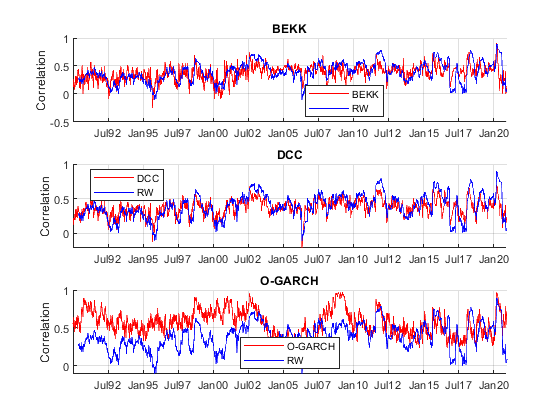

fign = fign+1;

% Calculating a 100 day rolling window correlation estimates

win_size = 100;
rw_corr = nan(T,1);

for i = win_size:T
    lower_index = i-win_size+1;
    upper_index = i;
    returns_subset = demeaned_returns(lower_index:upper_index , :) ;
    corr_matrix = corr(returns_subset);
    rw_corr(i,1) = corr_matrix(1,2);
end

% Plotting the rolling window correlations and the correlations estimated using each model

figure(fign)
subplot(3,1,1)
hold on;
grid on;
title('BEKK')
ylabel('Correlation')
plot(dn,corrBEKK,'r',dn,rw_corr,'b') % Plotting the BEKK model conditional correlations between the two stocks
datetick('x',12,"keeplimits"); 
legend({'BEKK','RW'},'location','best');
subplot(3,1,2)
hold on;
grid on;
title('DCC')
ylabel('Correlation')
plot(dn,corrDCC,'r',dn,rw_corr,'b')
datetick('x',12,"keeplimits"); 
legend({'DCC','RW'},'location','best');
subplot(3,1,3)
hold on;
grid on;
title('O-GARCH')
plot(dn,corrOGARCH,'r',dn,rw_corr,'b')
ylabel('Correlation')
datetick('x',12,"keeplimits"); 
legend({'O-GARCH','RW'},'location','best');

fign = fign+1;
% We can observe that the BEKK and DCC models are much better than O-GARCH
% Let's now further compare the estimates produced by the above models to choose the best performing model

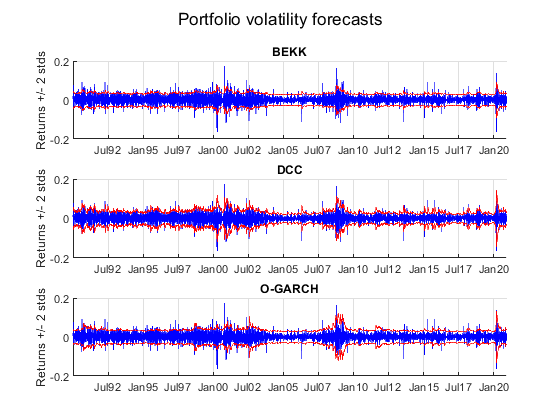

% Plotting the portfolio volatility estimates of the models

figure(fign)
subplot(3,1,1)
hold on;
grid on;
title('BEKK')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * portfolio_vol_BEKK,'r', dn , -2 * portfolio_vol_BEKK,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,2)
hold on;
grid on;
title('DCC')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * portfolio_vol_DCC,'r', dn , -2 * portfolio_vol_DCC,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,3)
hold on;
grid on;
title('O-GARCH')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * portfolio_vol_OGARCH,'r', dn , -2 * portfolio_vol_OGARCH,'r')
datetick('x',12,"keeplimits"); 
sgtitle('Portfolio volatility forecasts')

fign = fign+1; 

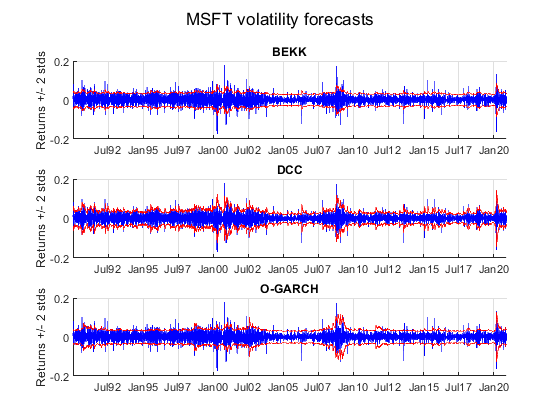

% Plotting MSFT volatility estimates of the models

figure(fign)
subplot(3,1,1)
hold on;
grid on;
title('BEKK')
ylabel('Returns +/- 2 stds')
plot(dn , log_returns(:,1) ,'b', dn , 2 * sqrt(MSFT_BEKK_var) ,'r', dn , -2 * sqrt(MSFT_BEKK_var) ,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,2)
hold on;
grid on;
title('DCC')
ylabel('Returns +/- 2 stds')
plot(dn , log_returns(:,1) ,'b', dn , 2 * sqrt(MSFT_DCC_var) ,'r', dn , -2 * sqrt(MSFT_DCC_var) ,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,3)
hold on;
grid on;
title('O-GARCH')
ylabel('Returns +/- 2 stds')
plot(dn , log_returns(:,1) ,'b', dn , 2 * sqrt(MSFT_OGARCH_var) ,'r', dn , -2 * sqrt(MSFT_OGARCH_var) ,'r')
datetick('x',12,"keeplimits"); 
sgtitle('MSFT volatility forecasts')

fign = fign+1;

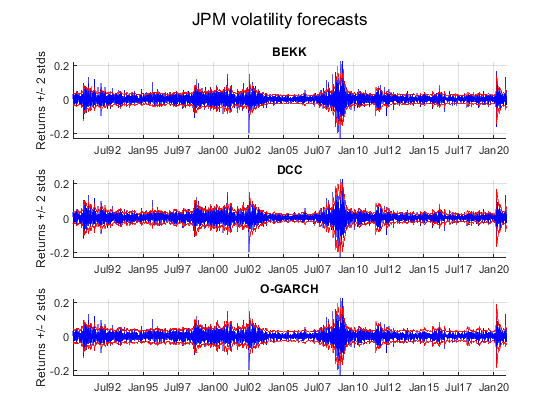

% Plotting JPM volatility estimates of the models

figure(fign)
subplot(3,1,1)
hold on;
grid on;
title('BEKK')
ylabel('Returns +/- 2 stds')
plot(dn , log_returns(:,2) ,'b', dn , 2 * sqrt(JPM_BEKK_var) ,'r', dn , -2 * sqrt(JPM_BEKK_var) ,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,2)
hold on;
grid on;
title('DCC')
ylabel('Returns +/- 2 stds')
plot(dn , log_returns(:,2) ,'b', dn , 2 * sqrt(JPM_DCC_var) ,'r', dn , -2 * sqrt(JPM_DCC_var) ,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,3)
hold on;
grid on;
title('O-GARCH')
ylabel('Returns +/- 2 stds')
plot(dn , log_returns(:,2) ,'b', dn , 2 * sqrt(JPM_OGARCH_var) ,'r', dn , -2 * sqrt(JPM_OGARCH_var) ,'r')
datetick('x',12,"keeplimits");
sgtitle('JPM volatility forecasts')

fign = fign+1;
% We can conlude from the above plots that DCC is superior to BEKK and O-GARCH in
% effectively capturing changes in volatility. This is especially true in
% the 2008 where there are big returns fluctuations.

% Thus, on the basis of the above results we will be using the DCC-GARCH(1,1) model for the VaR calculations.

# Now we proceed with Univariate volatility models

demeaned_portfolio_returns = portfolio_returns - mean(portfolio_returns); % De-meaning portfolio log-returns

% Fitting a GARCH(1,1) model with Normal innovations

[garch_params,garch_ll,garch_portfolio_var,garch_vcv] = tarch(demeaned_portfolio_returns,1,0,1);

____________________________________________________________
   Diagnostic Information

Number of variables: 3

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         -20571.9                          53.5
     1          12         -20575.9     0.00236335             23  
     2          16           -20577              1             18  
     3          20         -20579.9              1           7.31  
     4          24         -20580.2              1           4.05  
     5          28         -20580.3              1           5.01  
     6        

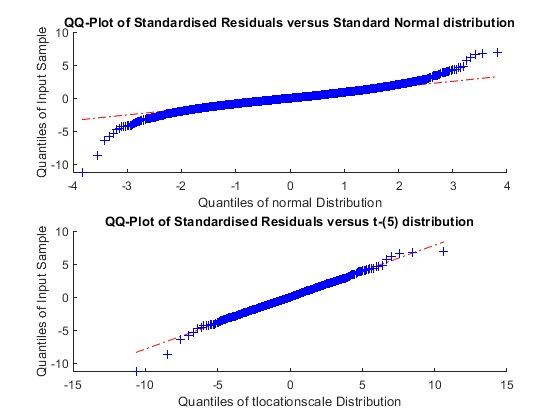

garch_resids = demeaned_portfolio_returns ./ sqrt(garch_portfolio_var); % Calculating the standardised residuals (these have mean=0 and std=1) 

% QQ-Plots of the standardised residuals

figure(fign)
subplot(2,1,1)
qqplot(garch_resids , makedist('Normal')) % Standard normal  
title('QQ-Plot of Standardised Residuals versus Standard Normal distribution')
subplot(2,1,2)
qqplot(garch_resids , makedist('tLocationScale')) % t(5) with μ=0 and σ=1 
title('QQ-Plot of Standardised Residuals versus t-(5) distribution')

fign = fign+1;
% By observing the fat tails in the first QQ-plot, we suspect that t-GARCH models might be a better fit for the data

% t-GARCH(1,1)
[t_garch_params,t_garch_ll,t_garch_portfolio_var,t_garch_vcv] = tarch(demeaned_portfolio_returns,1,0,1,'STUDENTST');

____________________________________________________________
   Diagnostic Information

Number of variables: 4

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           5         -20904.1                           107
     1          15         -20948.4     0.00351949           28.6  
     2          20         -20952.8              1           18.9  
     3          25         -20958.5              1           17.7  
     4          30         -20959.6              1           8.75  
     5          35         -20960.5              1           7.47  
     6        

% Let's use a log-Likelihood ratio test to confirm that t-GARCH models are a better fit for the data 
LR1 = 2*(t_garch_ll - garch_ll);  

CV = chi2inv(0.99,1); % This is the 1% critcal value of a chi-square with one degree of freedom

% LR1 = 762.07 > 6.63 = CV, so we reject H0 at the 1% level and
% conclude that t-GARCH models are a better fit for the data. 

% Fitting a t-GJR-GARCH(1,1,1) model to the data
[t_gjr_params,t_gjr_ll,t_gjr_portfolio_var,t_gjr_vcv] = tarch(demeaned_portfolio_returns,1,1,1,'STUDENTST');

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            tarch_likelihood
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           6         -20953.2                          56.2
     1          18         -20966.9      0.0060658           27.5  
     2          24         -20971.6              1           14.6  
     3          30         -20973.8              1           7.81  
     4          36         -20974.3              1           7.63  
     5          42         -20975.3              1           5.82  
     6        

t_garch_portfolio_vol = sqrt(t_garch_portfolio_var); % Calculating portfolio volatilities
t_gjr_portfolio_vol = sqrt(t_gjr_portfolio_var);

% Conducting a log-likelihood ratio test for the statistical significance of the leverage parameter γ in GJR

LR2 = 2*(t_gjr_ll - t_garch_ll); % test statistic  

% LR2 = 29.93 > 6.63 = CV, we can conclude that the t-GJR-GARCH(1,1,1) model is statistically superior at the 1% level


% Now we test the statistical significance of the t-GJR-GARCH(1,1,1) model parameters

t_gjr_params_SE = nan(5,1); % We have 5 parameters for this model

for i = 1:5
    t_gjr_params_SE(i,1) = sqrt(t_gjr_vcv(i,i)); % Diagonal elements are the variances of the parameters
end


t_gjr_params_tScores = t_gjr_params ./ t_gjr_params_SE ; % t = (estimated param. - 0) / ( SE(estimated param.) ) 

p_values = 2*(1-normcdf(t_gjr_params_tScores)) ;

t_gjr_param_table = array2table([t_gjr_params , t_gjr_params_SE , t_gjr_params_tScores,p_values],...
    "VariableNames",["Estimated parameter value","Standard errors","t-scores","P-values"],...
    "RowNames",({'ω','α','γ','β','ν(df)'})) 

t_gjr_param_table = 5×4 table
             Estimated parameter value    Standard errors    t-scores     P-values 
             _________________________    _______________    ________    __________

    ω               2.9619e-06              9.3846e-07        3.1562      0.0015986
    α                 0.059611                0.010121          5.89     3.8618e-09
    γ                 0.062478                0.015471        4.0384     5.3808e-05
    β                  0.90892                0.013629        66.692              0
    ν(df)               5.3266                 0.33164        16.061              0


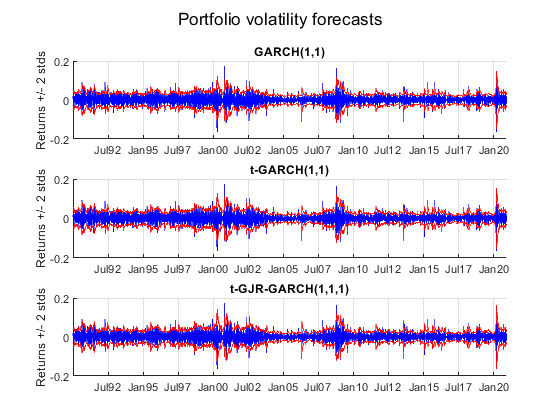

% We can see that all parameters are statistically significant

% Plotting the Portfolio volatility forecasts of the 3 GARCH-type models

figure(fign)
subplot(3,1,1)
hold on;
grid on;
title('GARCH(1,1)')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * sqrt(garch_portfolio_var) ,'r', dn , -2 * sqrt(garch_portfolio_var) ,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,2)
hold on;
grid on;
title('t-GARCH(1,1)')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * t_garch_portfolio_vol ,'r', dn , -2 * t_garch_portfolio_vol ,'r')
datetick('x',12,"keeplimits"); 
subplot(3,1,3)
hold on;
grid on;
title('t-GJR-GARCH(1,1,1)')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * t_gjr_portfolio_vol ,'r', dn , -2 * t_gjr_portfolio_vol ,'r')
datetick('x',12,"keeplimits");
sgtitle('Portfolio volatility forecasts')

fign = fign+1;

% We can observe that all 3 models produce quite satisfactory volatility forecasts, with t-GJR-Garch(1,1,1) performing better extreme negative returns.
% Hence we can conclude that t-GJR-GARCH(1,1,1) is the best performing model to be used for our VaR calculations.

# VaR calculations assuming Student's t returns using multivariate DCC-GARCH(1,1) & univariate t-GJR-GARCH(1,1,1)

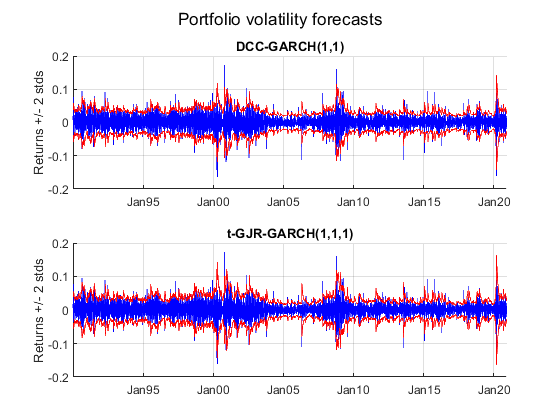

% Before proceeding to VaR calculations, let's compare the estimates of the best performing Multivariate and Univariate portfolio volatility forecasts

figure(fign)
subplot(2,1,1)
hold on;
grid on;
title('DCC-GARCH(1,1)')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * portfolio_vol_DCC ,'r', dn , -2 * portfolio_vol_DCC ,'r')
datetick('x',12,"keeplimits"); 
subplot(2,1,2)
hold on;
grid on;
title('t-GJR-GARCH(1,1,1)')
ylabel('Returns +/- 2 stds')
plot(dn , portfolio_returns ,'b', dn , 2 * t_gjr_portfolio_vol ,'r', dn , -2 * t_gjr_portfolio_vol ,'r')
datetick('x',12,"keeplimits");
sgtitle('Portfolio volatility forecasts')

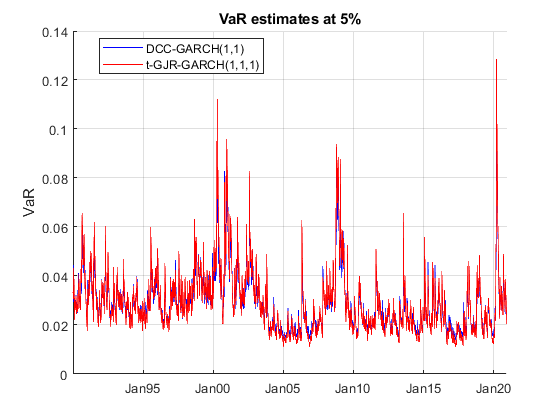

fign = fign+1; 

% Results are extremely close with the univariate model performing slightly better in extreme negative return shocks.


% Let's now calculate a 5% VaR series using the two models
% We assume t-distributed conditional returns for the portfolio

DCC_VaR = nan(T,1);
gjr_VaR = nan(T,1); 
p = 0.05; 
df = t_gjr_params(5,1); % We need the estimated DF for the standardised residuals (rt/σt) 

% For simplicity, we assume a portfolio value of 1 

gjr_VaR(:,1) = -tinv(p,df) * t_gjr_portfolio_vol * sqrt((df-2)/df); % t-GJR-GARCH(1,1,1)
DCC_VaR(:,1) = -tinv(p,df) * portfolio_vol_DCC * sqrt((df-2)/df); % DCC-GARCH(1,1)


% Plotting the VaR estimates

figure(fign)
hold on;
grid on;
title('VaR estimates at 5%')
ylabel('VaR')
plot(dn , DCC_VaR ,'b', dn , gjr_VaR ,'r')
legend({'DCC-GARCH(1,1)','t-GJR-GARCH(1,1,1)'},'location','best');
datetick('x',12,"keeplimits"); 

fign = fign+1;

% We notice that they are very similar, although in some cases t-GJR-GARCH VaR estimates are higher. 

# Backtesting VaR forecasts

% We now calculate the Violation Ratio for each series

hit_DCC = portfolio_returns < - DCC_VaR ; % Hit sequence using DCC VaR estimates
hit_GJR = portfolio_returns < - gjr_VaR ; % Hit sequence using t-GJR-GARCH VaR estimates

VR_DCC = sum(hit_DCC) / (p * T) ; % VR=0.849
VR_gjr = sum(hit_GJR) / (p * T) ; % VR=0.849

% In both cases, VR = 0.85 which is an acceptable value. However, both models seem to overforecast risk since VR<1.


% Unconditional Coverage Test to see if violations are happening at the expected frequency (ie. at 5%)

% H0: p = 5% and H1: p != 5% 

% For DCC
p_mle_DCC = sum(hit_DCC) / T ; % MLE estimate for the true probability of violation
V1_DCC = sum(hit_DCC); % Number of violations 
V0_DCC = T - V1_DCC; % Number of non-violations
LLR_DCC = log(1-p) * V0_DCC + log(p) * V1_DCC ; % Constrained (under H0) log-likelihood value
LLU_DCC = log(1-p_mle_DCC) * V0_DCC + log(p_mle_DCC) * V1_DCC ;  % Unconstrained (evaluated at the MLE) log-likelihood value
TS_DCC = -2 * ( LLR_DCC - LLU_DCC ); % Test statistic = 9.882
p_DCC = 1 - chi2cdf(TS_DCC,1) ; % P-value = 0.0017 < 0.05

% For t-GJR_GARCH
p_mle_GJR = sum(hit_GJR) / T ; % MLE estimate for the true probability of violation
V1_GJR = sum(hit_GJR); % Number of violations 
V0_GJR = T - V1_GJR; % Number of non-violations
LLR_GJR = log(1-p) * V0_GJR + log(p) * V1_GJR ; % Constrained (under H0) log-likelihood value
LLU_GJR = log(1-p_mle_GJR) * V0_GJR + log(p_mle_GJR) * V1_GJR ;  % Unconstrained (evaluated at the MLE) log-likelihood value
TS_GJR = -2 * ( LLR_GJR - LLU_GJR ); % Test statistic = 9.882
p_GJR = 1 - chi2cdf(TS_GJR,1) ; % P-Value = 0.0017 < 0.05

% In both cases, we reject H0 and conclude that Violations do not occur at a 5% frequency 
% Both models seem to overestimate risk as in both cases the estimated frequency from the data (p_mle) is 0.0424


% Conditional Coverage test to see if violations are independent of each other
% H0: violations are independent vs H1: violations are not independent (i.e violations cluster)

hit_sequences = [hit_DCC hit_GJR];

cond_cov_TS = nan(2,1); % Store test statistic for each test
cond_cov_p = nan(2,1); % Store p-value for each test
p00 = nan(2,1); 
p01 = nan(2,1); 
p10 = nan(2,1); 
p11 = nan(2,1); 

for k = 1:2
    
    hit_sequence = hit_sequences(:,k);
    j = zeros(t,4); % Matrix to store the results

    for i = 2:T
        j(i,1) = hit_sequence(i-1) == 0 & hit_sequence(i) == 0; % This entry is 1 if the condition is met, otherwise is 0 (acts as an indicator function) 
        j(i,2) = hit_sequence(i-1) == 0 & hit_sequence(i) == 1;
        j(i,3) = hit_sequence(i-1) == 1 & hit_sequence(i) == 0;
        j(i,4) = hit_sequence(i-1) == 1 & hit_sequence(i) == 1;  
    end
    
    
    V_00 = sum(j(:,1));
    V_01 = sum(j(:,2));
    V_10 = sum(j(:,3));
    V_11 = sum(j(:,4));
    p_00 = V_00 / (V_00 + V_01);
    p_01 = V_01 / (V_00 + V_01);
    p_10 = V_10 / (V_10 + V_11);
    p_11 = V_11 / (V_10 + V_11);
    p_hat = (V_01 + V_11) / (V_00 + V_01 + V_10 + V_11);
    LL_U = log(1 - p_hat)*(V_00 + V_10) + log(p_hat) * (V_01 + V_11); % Unrestricted Log-likelihood value
    LL_R = log(p_00)*(V_00) + log(p_01)*(V_01) + log(p_10)*(V_10) + log(p_11)*(V_11); % Restricted Log-likelihood value
    tt = -2 * (LL_U - LL_R);
    
    cond_cov_TS(k,1) = tt;
    cond_cov_p(k,1) = 1 - chi2cdf(tt,1);  
    p00(k,1) = p_00;
    p01(k,1) = p_01;
    p10(k,1) = p_10;
    p11(k,1) = p_11;
    
end

conditional_coverage_summary = array2table([cond_cov_TS , cond_cov_p, p00 , p10 , p01 , p11],...
    "VariableNames",["Test statistic","P-Value","p00","p10","p01","p11"],...
    "RowNames",({'DCC-GARCH(1,1)','t-GJR-GARCH(1,1,1)'}))

conditional_coverage_summary = 2×6 table
                          Test statistic    P-Value       p00        p10        p01         p11   
                          ______________    ________    _______    _______    ________    ________

    DCC-GARCH(1,1)            5.2962        0.021371    0.95876    0.93051    0.041243    0.069486
    t-GJR-GARCH(1,1,1)        1.1212         0.28966    0.95809    0.94562    0.041912    0.054381


% DCC: We reject H0 at the 5% level --> Violations are not independent
% t-GJR-GARCH: We do NOT reject H0 at the 5% level --> Violations are independent